# Laboratorium problemowe 2 - stanowisko wahadła rekacyjnego

## Sprawozdanie z zajęć nr 1

## Dawid Lisek

## Paweł Mańka

## Pon. 8.00 02.10.2023

# Opis przebiegu ćwiczenia.

Na zajęciach zapoznaliśmy się ze wszystkimi stanowiskami w laboratorium. Następnie po wyborze stanowiska należało zapoznać się z wybranym modelem oraz uruchomić obiekt. Po uruchomieniu obiektu zarejestrowaliśmy 3 przebiegi odpowiedzi modelu na wychylenie o pewien kąt z wyłączonym sterowaniem. Dodatkowo zarejestrowaliśmy również odpowiedź modelu na skok jednostkowy. 

# Pomiar drgań swobodnych.

Pomiary ruchu swobodnego wahadła polegały na puszczeniu wahadła z pewnego wychylenia oraz zarejestrowaniu drgań aż do ich wygaśnięcia.

Pomiar nr 1:

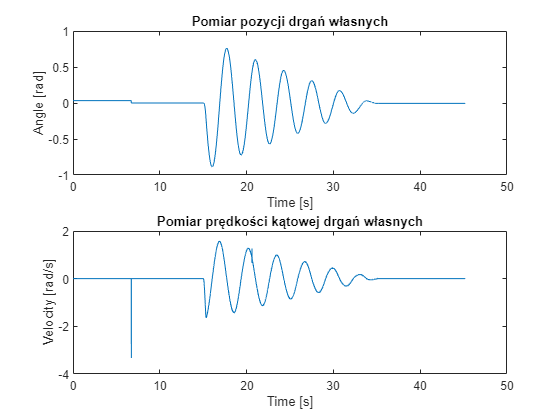

load doc\pomiary\lab_1\drgania_reczna_zmiana_polozenia.mat 

Pendulum_pos_1 = drgania_wlasne_1.signals(1).values;
Pendulum_velocity_1 = drgania_wlasne_1.signals(3).values;
time_1 = drgania_wlasne_1.time;

subplot(2, 1, 1)
plot(time_1, Pendulum_pos_1)
xlabel('Time [s]')
ylabel('Angle [rad]')
title('Pomiar pozycji drgań własnych')
subplot(2, 1, 2)
plot(time_1, Pendulum_velocity_1)
xlabel('Time [s]')
ylabel('Velocity [rad/s]')
title('Pomiar prędkości kątowej drgań własnych')

Pomiar nr 2:

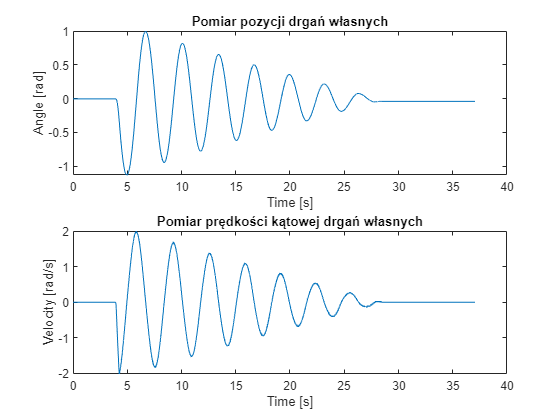

Pendulum_pos_2 = drgania_wlasne_2.signals(1).values;
Pendulum_velocity_2 = drgania_wlasne_2.signals(3).values;
time_2 = drgania_wlasne_2.time;

subplot(2, 1, 1)
plot(time_2, Pendulum_pos_2)
xlabel('Time [s]')
ylabel('Angle [rad]')
title('Pomiar pozycji drgań własnych')
subplot(2, 1, 2)
plot(time_2, Pendulum_velocity_2)
xlabel('Time [s]')
ylabel('Velocity [rad/s]')
title('Pomiar prędkości kątowej drgań własnych')

Pomiar nr 3:

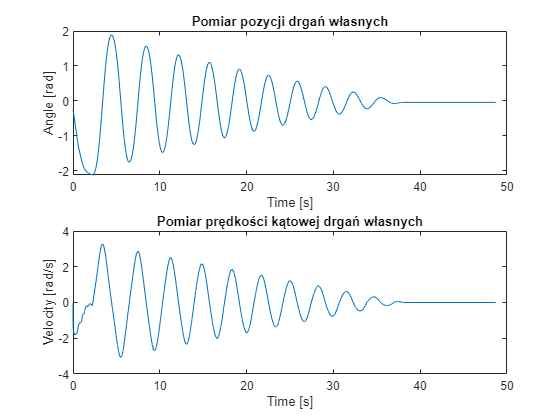

Pendulum_pos_3 = drgania_wlasne_3.signals(1).values;
Pendulum_velocity_3 = drgania_wlasne_3.signals(3).values;
time_3 = drgania_wlasne_3.time;

subplot(2, 1, 1)
plot(time_3, Pendulum_pos_3)
xlabel('Time [s]')
ylabel('Angle [rad]')
title('Pomiar pozycji drgań własnych')
subplot(2, 1, 2)
plot(time_3, Pendulum_velocity_3)
xlabel('Time [s]')
ylabel('Velocity [rad/s]')
title('Pomiar prędkości kątowej drgań własnych')

# Pomiar odpowiedzi na skok jednostkowy.

Pomiar ze sterowaniem 0.3

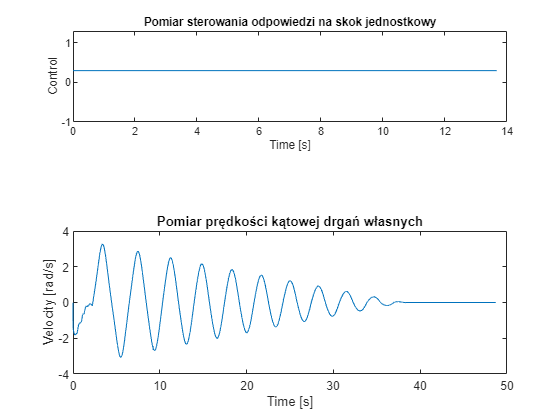

load doc\pomiary\lab_1\drgania_skok_jednostkowy.mat

step_response_position_1 = drgania_skok_jednostkowy_0_3.signals(1).values;
step_response_velocity_1 = drgania_skok_jednostkowy_0_3.signals(3).values;
step_response_control_1 = drgania_skok_jednostkowy_0_3.signals(7).values;
step_response_time_1 = drgania_skok_jednostkowy_0_3.time;

subplot(3, 1, 1)
plot(step_response_time_1, step_response_control_1)
xlabel('Time [s]')
ylabel('Control')
title('Pomiar sterowania odpowiedzi na skok jednostkowy')

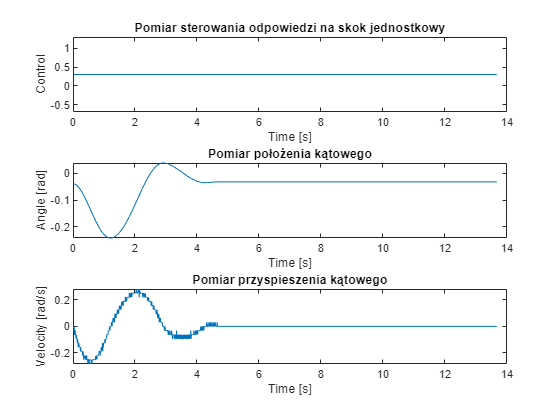

subplot(3, 1, 2)
plot(step_response_time_1, step_response_position_1)
xlabel('Time [s]')
ylabel('Angle [rad]')
title('Pomiar położenia kątowego')
subplot(3, 1, 3)
plot(step_response_time_1, step_response_velocity_1)
xlabel('Time [s]')
ylabel('Velocity [rad/s]')
title('Pomiar przyspieszenia kątowego')

Pomiar ze sterowaniem 1

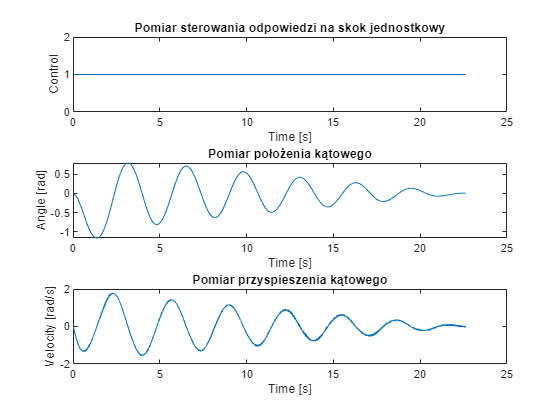

step_response_position_2 = drgania_skok_jednostkowy_1.signals(1).values;
step_response_velocity_2 = drgania_skok_jednostkowy_1.signals(3).values;
step_response_control_2 = drgania_skok_jednostkowy_1.signals(7).values;
step_response_time_2 = drgania_skok_jednostkowy_1.time;

subplot(3, 1, 1)
plot(step_response_time_2, step_response_control_2)
xlabel('Time [s]')
ylabel('Control')
title('Pomiar sterowania odpowiedzi na skok jednostkowy')
subplot(3, 1, 2)
plot(step_response_time_2, step_response_position_2)
xlabel('Time [s]')
ylabel('Angle [rad]')
title('Pomiar położenia kątowego')
subplot(3, 1, 3)
plot(step_response_time_2, step_response_velocity_2)
xlabel('Time [s]')
ylabel('Velocity [rad/s]')
title('Pomiar przyspieszenia kątowego')

Powyższe pomiary posłużą nam do zidentyfikowania parametrów modelu wahadła reakcyjnego.